close all;
grid = core.ScanGrid2D("CameraSensorWidth_mm", 7.2, "CameraSensorHeight_mm", 5.4, ...
    "FocalLength_mm", 6, "AngleResolution_dgr", 2, "ScanDistance_m", 2);


## **Untersuchung der Directivity unseres Microphones**

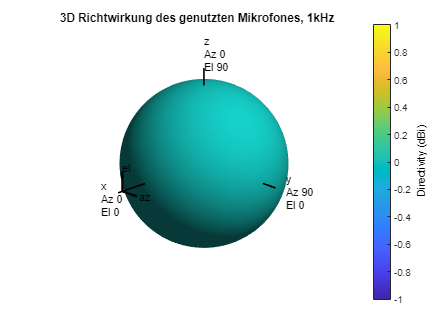

mic = phased.OmnidirectionalMicrophoneElement;
mic.FrequencyRange = [20 20e3];
mic.BackBaffled = false;

fc = 1e3;
ang = [0;0];

figure;
pattern(mic,fc,[-180:1:180],[-90:1:90],'CoordinateSystem','polar','Type','directivity', ...
    'ShowArray',true,'ShowLocalCoordinates',true,...
  'ShowColorbar', true, "PropagationSpeed", 343);
title("3D Richtwirkung des genutzten Mikrofones, 1kHz");

2D Azimuth Richtwirkung

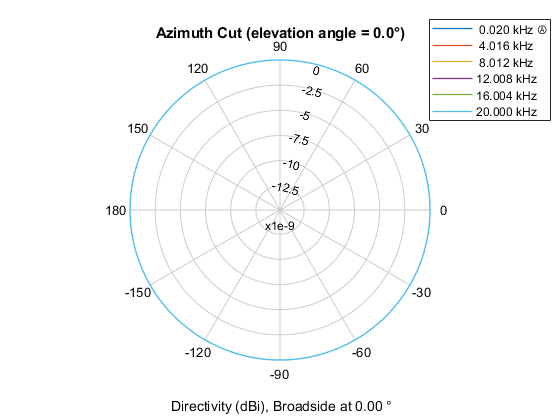


fc = linspace(20, 20e3, 6);
figure;
pattern(mic, fc, -180:180, 0, 'PropagationSpeed', 343,...
 'Type', 'directivity', 'CoordinateSystem', "polar");
title("Richtwirkung im Azimutalschnitt");

2D Elevation Richtwirkung

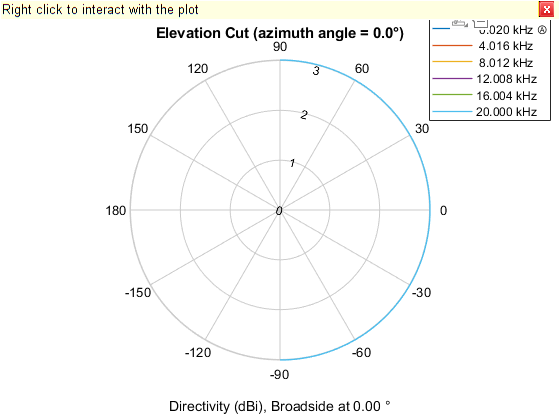

figure;
pattern(mic, fc, 0,[-90:1:90], 'PropagationSpeed', 343,...
 'Type', 'directivity', 'CoordinateSystem', "polar");
title("Richtwirkung im Elevationsschnitt");